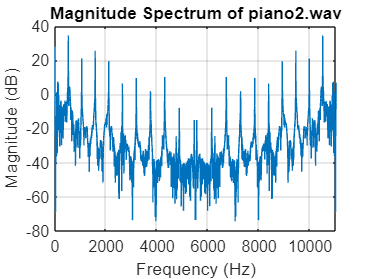

Fundamental Frequency for piano2.wav: 523.62 Hz


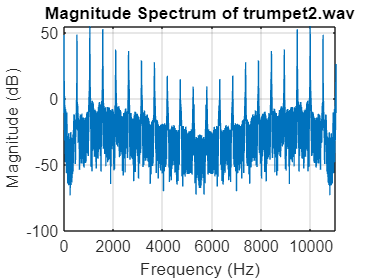

Fundamental Frequency for trumpet2.wav: 1047.21 Hz


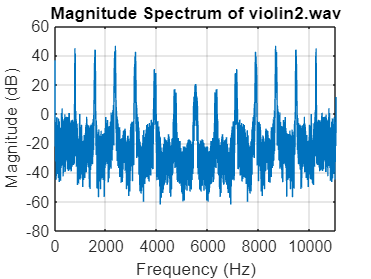

Fundamental Frequency for violin2.wav: 2369.12 Hz


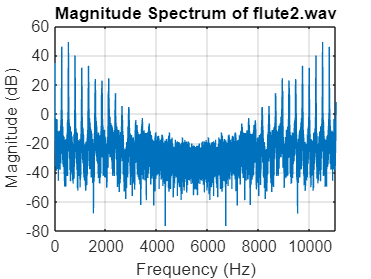

Fundamental Frequency for flute2.wav: 524.33 Hz


a=2;
fileNames = {'piano2.wav', 'trumpet2.wav', 'violin2.wav', 'flute2.wav'};


fundamentalFrequencies = zeros(1, numel(fileNames));


for i = 1:numel(fileNames)
   
    [audioData, sampleRate] = audioread(fileNames{i});

    
    fftResult = fft(audioData);
    numSamples = length(fftResult);
    freqs = (0:numSamples-1) * (sampleRate / numSamples);

    
    magnitudeSpectrumdB = 20 * log10(abs(fftResult));

    
    [~, peakIndex] = max(magnitudeSpectrumdB);

    
    fundamentalFrequency = freqs(peakIndex);

    
    fundamentalFrequencies(i) = fundamentalFrequency;

   
    figure;
    plot(freqs, magnitudeSpectrumdB);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    title(['Magnitude Spectrum of ' fileNames{i}]);
    grid on;
    
    
    fprintf('Fundamental Frequency for %s: %.2f Hz\n', fileNames{i}, fundamentalFrequency);
end



instrumentNames = {'Piano', 'Trumpet', 'Violin', 'Flute'};
T = table(instrumentNames', fundamentalFrequencies', 'VariableNames', {'Instrument', 'FundamentalFrequency_Hz'});
disp(T);

    Instrument     FundamentalFrequency_Hz
    ___________    _______________________

    {'Piano'  }            523.62         
    {'Trumpet'}            1047.2         
    {'Violin' }            2369.1         
    {'Flute'  }            524.33         



fileNames = {'flute1.wav','flute2.wav','flute3.wav','flute4.wav'};


fundamentalFrequencies = zeros(1, numel(fileNames));
for i = 1:numel(fileNames)
   
    [audioData, sampleRate] = audioread(fileNames{i});
    
    
    fftResult = fft(audioData);
    numSamples = length(fftResult);
    freqs = (0:numSamples-1) * (sampleRate / numSamples);

    
    magnitudeSpectrumdB = 20 * log10(abs(fftResult));

    
    [~, peakIndex] = max(magnitudeSpectrumdB);

    
    fundamentalFrequency = freqs(peakIndex);

    
    fundamentalFrequencies(i) = fundamentalFrequency;
     fprintf('Fundamental Frequency for %s: %.2f Hz\n', fileNames{i}, fundamentalFrequency);
end

Fundamental Frequency for flute1.wav: 1063.20 Hz
Fundamental Frequency for flute2.wav: 524.33 Hz
Fundamental Frequency for flute3.wav: 793.50 Hz
Fundamental Frequency for flute4.wav: 524.40 Hz




instrumentNames = {'flute1','flute2','flute3','flute4'};
T = table(instrumentNames', fundamentalFrequencies', 'VariableNames', {'Instrument', 'FundamentalFrequency_Hz'});
disp(T);

    Instrument    FundamentalFrequency_Hz
    __________    _______________________

    {'flute1'}            1063.2         
    {'flute2'}            524.33         
    {'flute3'}             793.5         
    {'flute4'}             524.4         



[y, Fs]=audioread("manasa1.wav");
fftResult = fft(y);
numSamples = length(fftResult);
freqs = (0:numSamples-1) * (Fs / numSamples);
magnitudeSpectrumdB = 20 * log10(abs(fftResult));
[~, peakIndex] = max(magnitudeSpectrumdB);
fundamentalFrequency_reference = freqs(peakIndex)

fundamentalFrequency_reference = 1.0e+03 *

    1.4958    1.4958


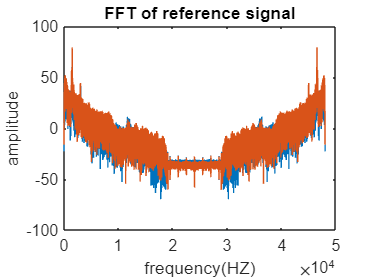

plot(freqs,magnitudeSpectrumdB)

title("FFT of reference signal")
xlabel("frequency(HZ)")
ylabel("amplitude")

fundamentalFrequencies = 1.0e+03 *

    1.4761    1.4761


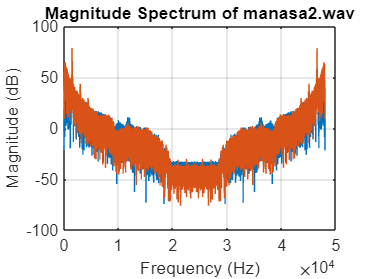

fundamentalFrequencies = 1.0e+03 *

    1.4559    1.4559


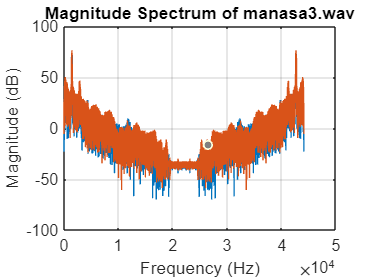

fundamentalFrequencies = 1.0e+03 *

    1.4559    1.4559


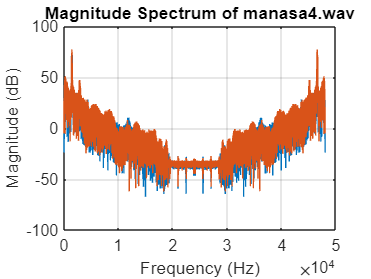

fundamentalFrequencies = 1.0e+03 *

    1.4559    1.4559


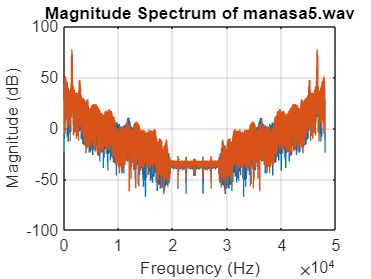

fileNames = {'manasa2.wav','manasa3.wav','manasa4.wav','manasa5.wav'};

for i = 1:numel(fileNames)
   
    [audioData, Fs] = audioread(fileNames{i});
    
    
    fftResult = fft(audioData);
    numSamples = length(fftResult);
    freqs = (0:numSamples-1) * (Fs / numSamples);

    
    magnitudeSpectrumdB = 20 * log10(abs(fftResult));

    
    [~, peakIndex] = max(magnitudeSpectrumdB);

    
    fundamentalFrequency = freqs(peakIndex);

    fundamentalFrequencies = zeros(1, numel(fileNames));
    fundamentalFrequencies = fundamentalFrequency
    
    figure;
    plot(freqs, magnitudeSpectrumdB);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    title(['Magnitude Spectrum of ' fileNames{i}]);
    grid on;
    
end

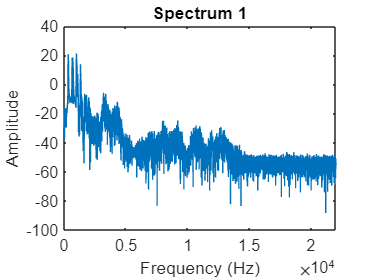

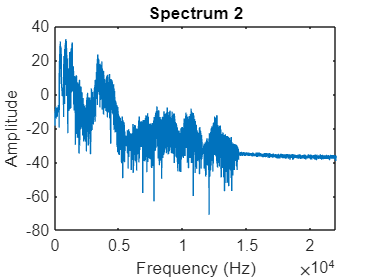

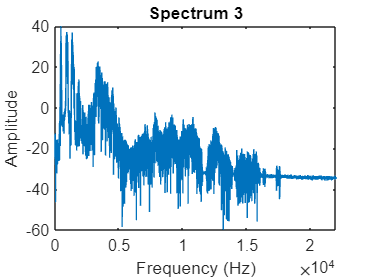

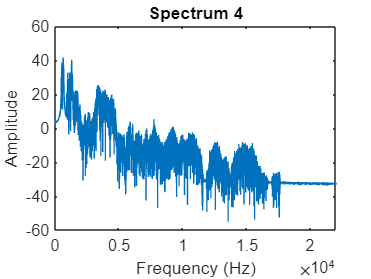

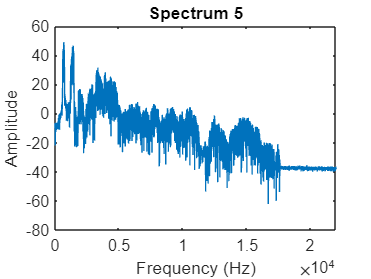

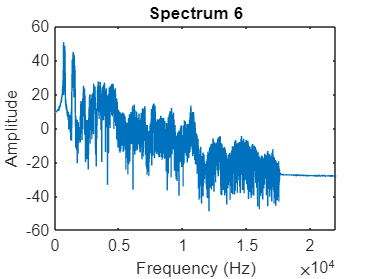

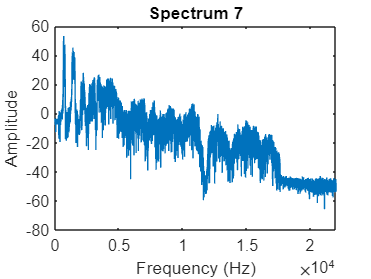

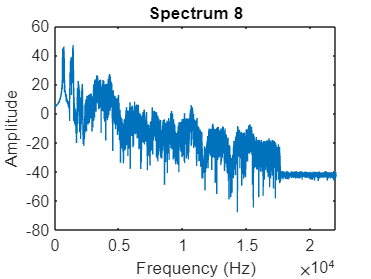


[audio_data, sample_rate] = audioread('Opera.wav');
num_spectrum = 10;
% Create and compare spectra for each window
for i = 1:num_spectrum
    start_idx = (i - 1) * 22000 + 1;
    end_idx = start_idx + 22000 - 1;
    
    % Extract the window of audio data
    spectrum_ = audio_data(start_idx:end_idx);
    
    % Compute the spectrum using the FFT
    spectrum = 20*log10(abs(fft(spectrum_)));

    
    % Calculate the corresponding frequency axis
    frequency_axis = linspace(0, sample_rate / 2, 20000 / 2 + 1);
    
    
    
    % Plot the spectrum for this window
    figure;
    plot(frequency_axis, spectrum(1:length(frequency_axis)));
    title(sprintf('Spectrum %d', i));
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    
    % Adjust the x-axis limits for a better view
    xlim([0, 22000]);  % Adjust the range as needed
end

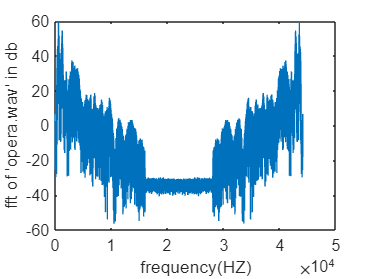

 figure
 numSamples = length(fft(audio_data));
 freqs = (0:numSamples-1) * (sample_rate / numSamples);
 
 plot(freqs,20*log10(abs(fft(audio_data))))


xlabel("frequency(HZ)")
ylabel("fft of 'opera.wav' in db")

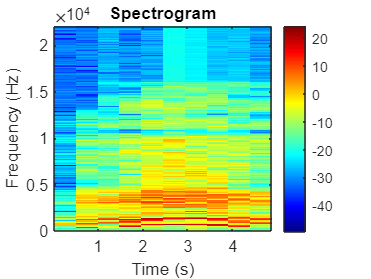


 % Example: Load an audio file
[y, Fs] = audioread('Opera.wav');
window_length = 22000; 
overlap = 512;         % Overlap between consecutive windows in samples
nfft = 22000;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f, t] = spectrogram(y, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram');
colorbar;  % Add a colorbar to show magnitude values